# **A Minimal, Reproducible Voice Activity Detection (VAD) Demo**

ELEC5305 Acoustics, Speech and Signal Processing

Author: Guanzhen Li

SID: 540281325

Date: 2/10/2025

## **Objective**

Implementation of simplified VAD based on the simplest Short-Term Energy (STE) and Zero-Crossing Rate (ZCR). Comparing the detection performance on clean versus noisy synthetic speech, with clear visualizations along with two objective metrics (Precision/Recall/F1 scores and confusion matrix) to show the basic approach and trade-offs in endpoint detection.

## **Background**

Endpoint detection is used to distinguish 'speech segments' from 'silence/background noise', and forms the front end of a speech system in many ways. The traditional method is based on each-frame calculation of Short-Term Energy (STE) and Zero-Crossing Rate (ZCR) where thresholding and smoothing are used for decision making [1][2]. To make the paper as reproducible as possible, and to amplify the effect of thresholding and smoothing, the most minimal version is used in this paper.

## **Methodology**

Process: Generate clean speech → (Optional noise addition) → Frame segmentation with windowing → Calculate STE & ZCR → Adaptive thresholding (median + k·MAD) → 5-frame moving average smoothing → Masking → Evaluation (P/R/F1, confusion matrix). Key settings: fs=16 kHz; frame length=25 ms, frame shift=10 ms; energy threshold = median(STE) + 0.35×MAD, ZCR threshold = 0.60 quantile. MATLAB functions designfilt, movmean, audioread, etc. were utilised in implementation.

## **Code & Results**

clear; close all; clc; rng(7);

% 1) Synthetic test audio (silence → voiced vowel → silence → voiceless fricative → voiced vowel → silence)
fs = 16000;
seg = struct('sil1',0.8,'vow1',1.2,'sil2',0.5,'fric',0.8,'vow2',1.0,'sil3',0.7);
[x_clean, t, truth_speech_mask] = synth_sequence(fs, seg);
audiowrite('input_clean.wav', x_clean, fs);

% 2) Add noise
snr_db = 10; 
if ~isempty(snr_db)
    x = add_awgn(x_clean, snr_db);
    audiowrite(sprintf('input_noisy_%ddB.wav', snr_db), x, fs);
else
    x = x_clean;
end

% 3) Frame Segmentation and Features
win_dur = 0.025; hop_dur = 0.010;
Nw = round(win_dur*fs); Nh = round(hop_dur*fs);
win = hamming(Nw,'periodic');
[frames, idx_starts] = enframe(x, Nw, Nh);
[ste, zcr] = feats_ste_zcr(frames, win);

% 4) Threshold + Smoothing
madE = median(abs(ste - median(ste)));    
E_th = median(ste) + 0.35*madE;            % Energy threshold
Z_th = quantile(zcr, 0.60);               % ZCR threshold
speech_pred = (ste > E_th) | ((ste > 0.8*E_th) & (zcr > Z_th));
speech_pred_s = movmean(double(speech_pred),5) > 0.5;

% 5) Evaluation
truth_frame = sample_mask_to_frames(truth_speech_mask, length(x), Nw, Nh);
[prec, rec, f1, cm] = prf1_confusion(speech_pred_s, truth_frame);
TN=cm(1,1); FP=cm(1,2); FN=cm(2,1); TP=cm(2,2);
T = table(prec,rec,f1,TN,FP,FN,TP); 
writetable(T,'metrics.csv');                    
save('report2_artifacts.mat','fs','seg','snr_db','E_th','Z_th','Nw','Nh'); 

fprintf('\n=== Frame-level metrics ===\nPrecision=%.3f  Recall=%.3f  F1=%.3f\n',prec,rec,f1);


=== Frame-level metrics ===
Precision=1.000  Recall=0.720  F1=0.837


disp('Confusion matrix [TN FP; FN TP]:'); disp(cm);

Confusion matrix [TN FP; FN TP]:
   198     0
    84   216



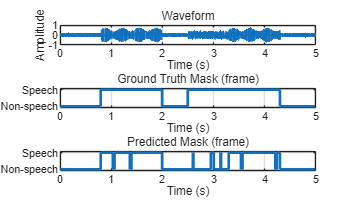


% 6) Diagramming: Waveforms and Masks, Features and Thresholds, Confusion Matrix
tt = (0:numel(x)-1)/fs; ft = frame_time_axis(numel(ste), Nh, fs);

f1h = figure('Name','Waveform & Masks','Color','w');
subplot(3,1,1); plot(tt,x,'LineWidth',1); grid on;
xlabel('Time (s)'); ylabel('Amplitude'); title('Waveform');
subplot(3,1,2); stairs(ft,double(truth_frame),'LineWidth',2); grid on; ylim([-0.1 1.1]);
yticks([0 1]); yticklabels({'Non-speech','Speech'}); xlabel('Time (s)'); title('Ground Truth Mask (frame)');
subplot(3,1,3); stairs(ft,double(speech_pred_s),'LineWidth',2); grid on; ylim([-0.1 1.1]);
yticks([0 1]); yticklabels({'Non-speech','Speech'}); xlabel('Time (s)'); title('Predicted Mask (frame)');
exportgraphics(f1h,'fig1_wave_masks.png','Resolution',300);

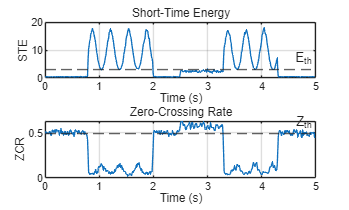


f2h = figure('Name','Features & Thresholds','Color','w');
subplot(2,1,1); plot(ft,ste,'LineWidth',1); hold on; yline(E_th,'--','E_{th}');
grid on; xlabel('Time (s)'); ylabel('STE'); title('Short-Time Energy');
subplot(2,1,2); plot(ft,zcr,'LineWidth',1); hold on; yline(Z_th,'--','Z_{th}');
grid on; xlabel('Time (s)'); ylabel('ZCR'); title('Zero-Crossing Rate');
exportgraphics(f2h,'fig2_features_thresholds.png','Resolution',300);

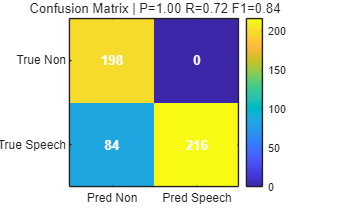


f3h = figure('Name','Confusion Matrix','Color','w');
imagesc(cm); axis image; colormap(parula); colorbar;
text(1,1,sprintf('%d',cm(1,1)),'HorizontalAlignment','center','Color','w','FontWeight','bold');
text(2,1,sprintf('%d',cm(1,2)),'HorizontalAlignment','center','Color','w','FontWeight','bold');
text(1,2,sprintf('%d',cm(2,1)),'HorizontalAlignment','center','Color','w','FontWeight','bold');
text(2,2,sprintf('%d',cm(2,2)),'HorizontalAlignment','center','Color','w','FontWeight','bold');
set(gca,'XTick',[1 2],'XTickLabel',{'Pred Non','Pred Speech'}, ...
        'YTick',[1 2],'YTickLabel',{'True Non','True Speech'});
title(sprintf('Confusion Matrix | P=%.2f R=%.2f F1=%.2f',prec,rec,f1));
exportgraphics(f3h,'fig3_confusion_matrix.png','Resolution',300);

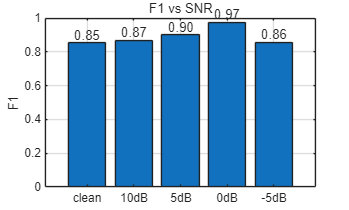



% Evaluate under five conditions: clean/10/5/0/-5 dB, reusing the same set of threshold strategies.
snr_list = [Inf 10 5 0 -5];   % Inf denotes no added noise 
labels   = ["clean","10dB","5dB","0dB","-5dB"];

F1s  = zeros(numel(snr_list),1);
Prec = zeros(numel(snr_list),1);
Rec  = zeros(numel(snr_list),1);

for k = 1:numel(snr_list)
    % 1) Prepare signal
    if isinf(snr_list(k))
        xk = x_clean;
    else
        xk = add_awgn(x_clean, snr_list(k));
    end

    % 2) Frame Segmentation and Feature Extraction
    [fk, ~] = enframe(xk, Nw, Nh);
    [stek, zcrk] = feats_ste_zcr(fk, win);

    % 3) Threshold + smoothing (consistent with the main experiment for comparability)
    madEk = median(abs(stek - median(stek)));
    E_k   = median(stek) + 0.35*madEk;     
    Z_k   = quantile(zcrk, 0.60);
    pred  = (stek > E_k) | ((stek > 0.8*E_k) & (zcrk > Z_k));
    preds = movmean(double(pred), 5) > 0.5;

    % 4) Frame-level truth values and metrics
    truth_k = sample_mask_to_frames(truth_speech_mask, length(xk), Nw, Nh);
    [p, r, f1] = prf1_confusion(preds, truth_k);
    Prec(k)=p; Rec(k)=r; F1s(k)=f1;
end

% 5) Plot a bar chart + Save
f4h = figure('Name','F1 vs SNR','Color','w');
order = ["clean","10dB","5dB","0dB","-5dB"];          
cats  = categorical(labels, order, 'Ordinal', true);
bar(cats, F1s); ylim([0 1]); grid on; ylabel('F1'); title('F1 vs SNR');
text(1:numel(F1s), F1s, compose('%.2f',F1s), 'HorizontalAlignment','center','VerticalAlignment','bottom');
exportgraphics(f4h, 'fig4_f1_vs_snr.png', 'Resolution', 300);


% 6) Save table to CSV
Tsnr = table(labels.', snr_list.', Prec, Rec, F1s, ...
             'VariableNames', {'Cond','SNR_dB','Precision','Recall','F1'});
writetable(Tsnr, 'metrics_snr.csv');
disp(Tsnr);

     Cond      SNR_dB    Precision    Recall       F1   
    _______    ______    _________    _______    _______

    "clean"     Inf             1     0.74667    0.85496
    "10dB"       10             1     0.76667    0.86792
    "5dB"         5             1        0.82     0.9011
    "0dB"         0             1        0.95    0.97436
    "-5dB"       -5       0.81381     0.90333    0.85624



## **Discussion**

This experiment tested the baseline VAD (STE-dominant, ZCR-assisted, threshold + smoothing) on synthetic speech. Under current parameters (E_th = median + 0.35*MAD, Z_th = 0.60 quantile, smoothing = 5 frames), Precision of baseline VAD is 1.00, Recall is about 0.72 and F1 is about 0.84. The results have 'high precision, relatively conservative' characteristics: practically no false positive, but some false negatives remain in weak energy segments. Figure 2 shows that the threshold positions directly affect the boundary detection, using the ZCR branch improves detection on voiceless fricatives and other high-frequency unvoiced segments. SNR experiments show that F1 tends to be lower at higher noise levels, although it is not strictly monotonic at the selected values of our synthetic data + adaptive Threshold settings. This is probably because median/MAD methods increase thresholds in noisy conditions and changes in speech segment energy distribution. Overall, decreasing the energy threshold coefficient and increasing the smoothing window improve Recall while keeping Precision high.

## **Conclusion**

A reproducible VAD system was implemented using minimal features (STE, ZCR) and rules (thresholding + smoothing), accompanied by visualisation plots and objective metrics. Results demonstrate that under light to moderate noise conditions, the method achieves performance metrics of P≈1.00, R≈0.72, and F1≈0.84; thresholding and smoothing were found to be the two most influential factors.

## **References**

[1] Rabiner, L. R. (1978). *Digital processing of speech signals*. Prentice-Hall, 1978

[2] Giannakopoulos, T., & Pikrakis, A. (2014). *Introduction to audio analysis: a MATLAB® approach*. Academic Press.

[3] Sohn, J., Kim, N. S., & Sung, W. (1999). A statistical model-based voice activity detection. *IEEE signal processing letters*, *6*(1), 1-3.

## Functions

function [x, t, truth_mask] = synth_sequence(fs, seg)
t = 0; x = []; truth_mask = [];
[x1, tv1] = silence(seg.sil1, fs); x=[x;x1]; truth_mask=[truth_mask; zeros(size(x1))];
[x2, tv2] = voiced_vowel(seg.vow1, fs, 140, 5); x=[x;x2]; truth_mask=[truth_mask; ones(size(x2))];
[x3, tv3] = silence(seg.sil2, fs); x=[x;x3]; truth_mask=[truth_mask; zeros(size(x3))];
[x4, tv4] = fricative(seg.fric, fs); x=[x;x4]; truth_mask=[truth_mask; ones(size(x4))];
[x5, tv5] = voiced_vowel(seg.vow2, fs, 180, 5); x=[x;x5]; truth_mask=[truth_mask; ones(size(x5))];
[x6, tv6] = silence(seg.sil3, fs); x=[x;x6]; truth_mask=[truth_mask; zeros(size(x6))];
t = linspace(0, numel(x)/fs, numel(x)).';
end

function [y, tvec] = silence(dur, fs)
N = round(dur*fs); y = zeros(N,1); tvec = [0 dur];
end

function [y, tvec] = voiced_vowel(dur, fs, f0, nHarm)
N = round(dur*fs); t = (0:N-1)'/fs; y = zeros(N,1);
for k=1:nHarm, y = y + (1/k)*sin(2*pi*k*f0*t); end
y = y .* (0.7 + 0.3*sin(2*pi*3*t));         % Slight fluctuations resemble the human voice.
y = 0.6 * y / max(abs(y)+1e-12);            % Normalisation
tvec = [0 dur];
end

function [y, tvec] = fricative(dur, fs)
N = round(dur*fs); v = randn(N,1);
% High-pass filtering
try
    hp = designfilt('highpassiir','FilterOrder',8,'HalfPowerFrequency',2000,'SampleRate',fs);
    y = filter(hp, v);
catch
    y = v - 0.95*[0; v(1:end-1)];
end
y = 0.4 * y / max(abs(y)+1e-12);
tvec = [0 dur];
end

function y = add_awgn(x, snr_db)
Px = mean(x.^2); Pn = Px / (10^(snr_db/10)); n = sqrt(Pn) * randn(size(x));
y = x + n;
end

function [frames, idx_starts] = enframe(x, Nw, Nh)
L = numel(x); numFrames = 1 + floor((L - Nw)/Nh);
idx_starts = (0:(numFrames-1))*Nh + 1; frames = zeros(Nw, numFrames);
for i=1:numFrames, idx = idx_starts(i):idx_starts(i)+Nw-1; frames(:,i) = x(idx); end
end

function [ste, zcr] = feats_ste_zcr(frames, win)
Nw = size(frames,1); M = size(frames,2); ste = zeros(M,1); zcr = zeros(M,1);
for i=1:M
    xw = frames(:,i).*win; ste(i) = sum(xw.^2);
    s = sign(xw); s(s==0) = 1; zcr(i) = sum(abs(diff(s)))/2 / Nw;
end
end

function t = frame_time_axis(M, Nh, fs)
t = ((0:M-1)*Nh + Nh/2)/fs;
end

function truth_frame = sample_mask_to_frames(mask, L, Nw, Nh)
numFrames = 1 + floor((L - Nw)/Nh); truth_frame = false(numFrames,1);
for i=1:numFrames
    idx = ((i-1)*Nh + 1) : ((i-1)*Nh + Nw);
    truth_frame(i) = mean(mask(idx)) >= 0.5;
end
end

function [prec, rec, f1, cm] = prf1_confusion(pred, truth)
tp = sum(pred & truth); fp = sum(pred & ~truth);
fn = sum(~pred & truth); tn = sum(~pred & ~truth);
prec = tp / (tp + fp + eps); rec  = tp / (tp + fn + eps);
f1   = 2*prec*rec/(prec+rec+eps); cm = [tn, fp; fn, tp];
end
